close all;
clear;
clc;


## Part 1

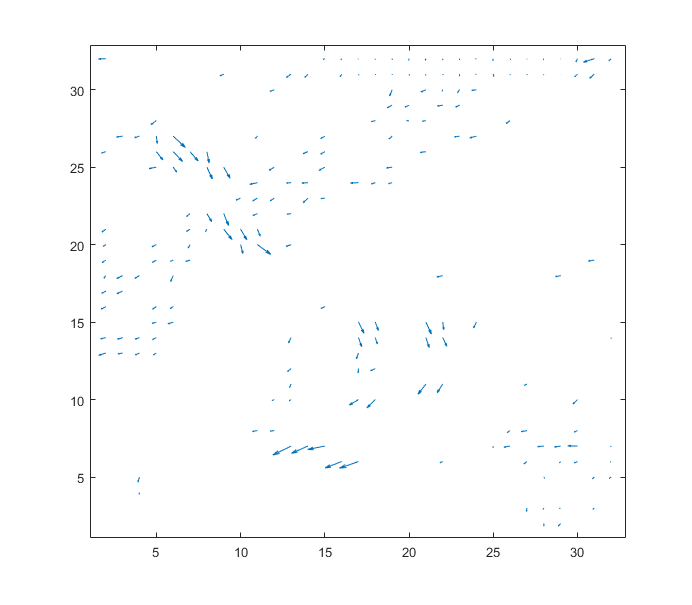

frames = im2double(imread("seq.gif","gif","Frames","all"));
dx = [1 -1];
dy = dx';
frames_dx = convn(frames(:,:,1,:), dx, "same");
frames_dy = convn(frames(:,:,1,:), dy, "same");
frames_dt = frames(:,:,1,2:size(frames,4)) - frames(:,:,1,1:size(frames,4)-1);

N = 16;
num_of_regions = 32;
t = 1;
flow = zeros(32,32,2,48);

for i=1:size(frames,4)-1
    for row=1:num_of_regions
        for col=1:num_of_regions
            reg_dx_t = frames_dx((row-1)*16 + 1:row*16,(col-1)*16 + 1:col*16,:,i)';
            reg_dy_t = frames_dy((row-1)*16 + 1:row*16,(col-1)*16 + 1:col*16,:,i)';
            A = [reg_dx_t(:)'; reg_dy_t(:)']';
            AtA = A' * A;
            
            reg_dt_t = frames_dt((row-1)*16 + 1:row*16,(col-1)*16 + 1:col*16,:,i)';
            b = -reg_dt_t(:);
            
            e = eig(AtA);
            if min(e) > t
                u = AtA \ (A' * b);
                flow(row,col,:,i) = u;
            end
        end
    end
end

for i=1:size(frames,4)-1
    hold all;
    imshow(frames(:,:,:,i),[]);
    q = quiver(flow(:,:,1,i), flow(:,:,2,i));
   
end